# Final Project: CNN Portion

**Author:** Jack Bonney

**Student ID:** 4555214

**D Value:** 14

This live-script will walk through the processing involved with performing CNN on an image classification dataset. The dataset used is a collection of playing cards for all 53 types, the 13 base cards in each suit and the joker card. The data will be run through the google mobilenetv2 pretrained model. 

% Initialization
clc
clear
D = 14; % Personalization, will be used for RNG seeding


## Model Parameters

trainFraction = 0.7; % How much of the total data should be training: 0-1
testFraction = 0.15; % How much is testing data, same as validation
valFraction = 0.15; % Further split training into train/validation
TotalTrials = 1; % How many total trials

## Sorting into Training and Testing Data

% LOADING THE DATA 
data = imageDatastore("input\","IncludeSubfolders",true,"LabelSource",'foldernames');
[values, cardTypes] = grp2idx(data.Labels); % Gets number values for each card type, and where they are in the datastore
% SORTING THE DATA INTO TRAINING AND TESTING
% Split into train/test
rng(D);  % Set rng for reproducability
[trainData, tempData] = splitEachLabel(data, trainFraction, 'randomized');
[valData, testData] = splitEachLabel(tempData, valFraction/(valFraction+testFraction), 'randomized');

## Showing success of train/test split

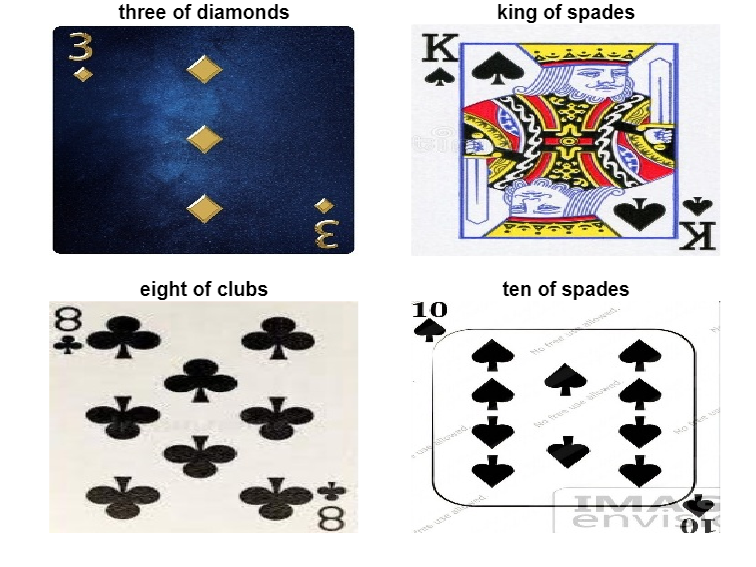

% Show traing images
testing = randperm(numel(trainData.Files),4);
datasetImagesTrain = figure('Position',[100,100,1000,1000]);
tiledlayout(2,2,'Padding','compact','TileSpacing','compact')
for idx = 1:4
    nexttile;
    img = readimage(trainData,testing(idx));
    imshow(img)
    axis off;
    title(string(trainData.Labels(testing(idx))));
end
filename = sprintf('trainImages.png');
outputFile = fullfile("figures/",filename);
exportgraphics(datasetImagesTrain,outputFile,'Resolution',1200);

% Show traing images
testing = randperm(numel(testData.Files),4);
datasetImageTest = figure('Position',[100,100,1000,1000]);
tiledlayout(2,2,'Padding','compact','TileSpacing','compact')
for idx = 1:4
    nexttile;
    img = readimage(testData,testing(idx));
    imshow(img)
    axis off;
    title(string(testData.Labels(testing(idx))));
end
filename = sprintf('testImages.png');
outputFile = fullfile("figures/",filename);
exportgraphics(datasetImageTest,outputFile,'Resolution',1200);

## Getting the CNN working via Mobilenetv2

For this I am using the pretrainined MobileNetv2 model. While good, it is quite large and built for 224x224 images, so a lot of what is done is to allow retraining for my data without having to retrain the entire model. 

% Set up the network
net = mobilenetv2;
lgraph = layerGraph(net);
% Swap the final layers with what I have
newLayers = [
    fullyConnectedLayer(max(values),'Name','fc_new')
    softmaxLayer('Name','softmax')
    classificationLayer('Name','cardOutput')
];
% Replacing layers
lgraph = replaceLayer(lgraph, lgraph.Layers(1).Name,imageInputLayer([96,96,3],'Name','input','Normalization','zerocenter'));
lgraph = replaceLayer(lgraph,'Logits',newLayers(1));
lgraph = replaceLayer(lgraph,'Logits_softmax',newLayers(2));
lgraph = replaceLayer(lgraph,'ClassificationLayer_Logits',newLayers(3));
% Freeze Layers
layers = lgraph.Layers;
connections = lgraph.Connections;
for i = 1:numel(layers)
    % Get name of current layer
    layerName = layers(i).Name;
    if contains(layerName,"block_16") || contains(layerName,"Conv_1") || strcmp(layerName,"fc_new")
        continue;
    end
    if isprop(layers(i),'WeightLearnRateFactor')
        layers(i).WeightLearnRateFactor = 0;
    end
    if isprop(layers(i),'BiasLearnRateFactor')
        layers(i).BiasLearnRateFactor = 0;
    end
    % Update the layer
    lgraph = replaceLayer(lgraph,layerName,lgraph.Layers(i));
end
% Get the training and validation splits
dataTrain = augmentedImageDatastore([96,96,3],trainData);
dataValid = augmentedImageDatastore([96,96,3],valData);
dataTest = augmentedImageDatastore([96,96,3],testData);
% Setting up the options for the algorithim
options = trainingOptions("adam",'MiniBatchSize',16,'MaxEpochs',5,'ValidationData',dataValid,'Verbose',false,'ExecutionEnvironment','gpu','ValidationFrequency',30);
% Run the model
[results,info] = trainNetwork(dataTrain,lgraph,options);

### Getting the Traing and Validation Accuarcy and Losses

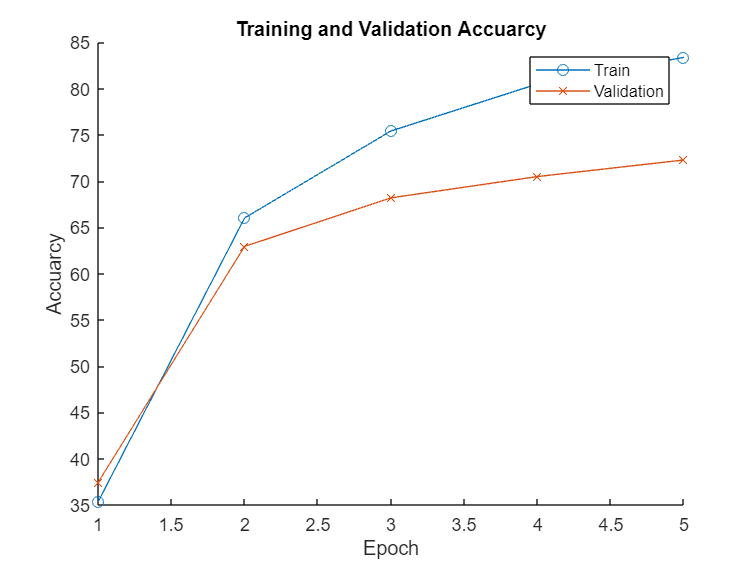

% Getting training vs testing
% Get the accuarcy per epoch
epochs = 5;
iterPerEpoch = floor(length(trainData.Files)/(16)); % Training data / number of minibatches
trainAcc = zeros(epochs,1);
trainLoss = zeros(epochs,1);
validAcc = zeros(epochs,1);
validLoss = zeros(epochs,1);
% Get validation by iteration to remove NaN
validAccIter = info.ValidationAccuracy(2:end);
validAccIter = validAccIter(~isnan(info.ValidationAccuracy(2:end)));
validLossIter = info.ValidationLoss(2:end);
validLossIter = validLossIter(~isnan(info.ValidationLoss(2:end)));
for e = 1:epochs
    trainAcc(e) = mean(info.TrainingAccuracy(1+(e-1)*iterPerEpoch:min(e*iterPerEpoch,length(info.TrainingAccuracy))));
    trainLoss(e) = mean(info.TrainingLoss(1+(e-1)*iterPerEpoch:min(e*iterPerEpoch,length(info.TrainingLoss))));
    validAcc(e) = mean(validAccIter(1+(e-1)*(length(validLossIter)/epochs):min(e*(length(validLossIter)/epochs),length(validAccIter))));
    validLoss(e) = mean(validLossIter(1+(e-1)*(length(validLossIter)/epochs):min(e*(length(validLossIter)/epochs),length(validLossIter))));
end
% Trimming validation
% Ploting the Training and Validation accuracy
accuarcy = figure;
hold on
plot(1:epochs, trainAcc,'-o')
plot(1:epochs, validAcc,'-x')
hold off
legend('Train','Validation')
title('Training and Validation Accuarcy')
xlabel('Epoch')
ylabel('Accuarcy')
filename = sprintf('finalCNNTrainValidAcc.png');
outputFile = fullfile("figures/",filename);
exportgraphics(accuarcy,outputFile,'Resolution',600);

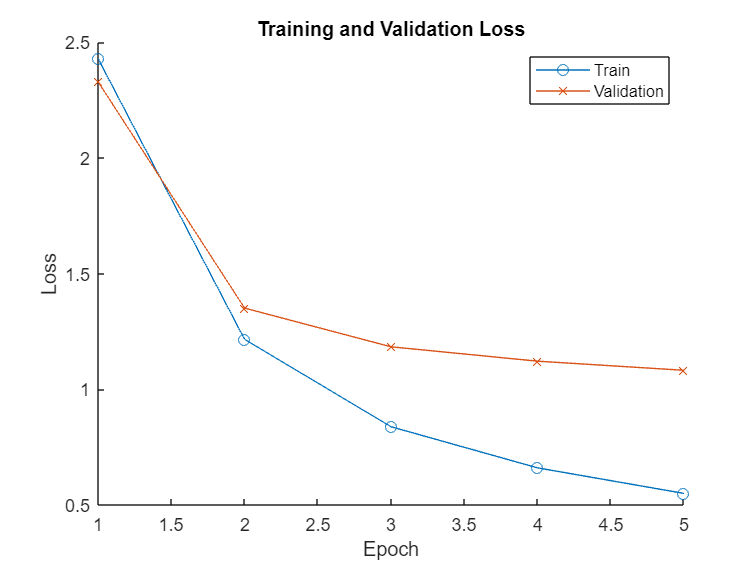

% Ploting the losses
losses = figure;
hold on
plot(1:epochs, trainLoss,'-o')
plot(1:epochs, validLoss, '-x')
hold off
legend('Train','Validation')
title('Training and Validation Loss')
xlabel('Epoch')
ylabel('Loss')
filename = sprintf('finalCNNTrainValidLoss.png');
outputFile = fullfile("figures/",filename);
exportgraphics(losses,outputFile,'Resolution',600);

% Get the final accuracy For train, valid, and test
prediction = classify(results, dataTrain);
trainAccuracyFinal = mean(prediction == trainData.Labels);
prediction = classify(results,dataValid);
valAccuracyFinal = mean(prediction == valData.Labels);
prediction = classify(results, dataTest);
testAccuracyFinal = mean(prediction == testData.Labels);

### Getting Final Validation vs Test Accuracy

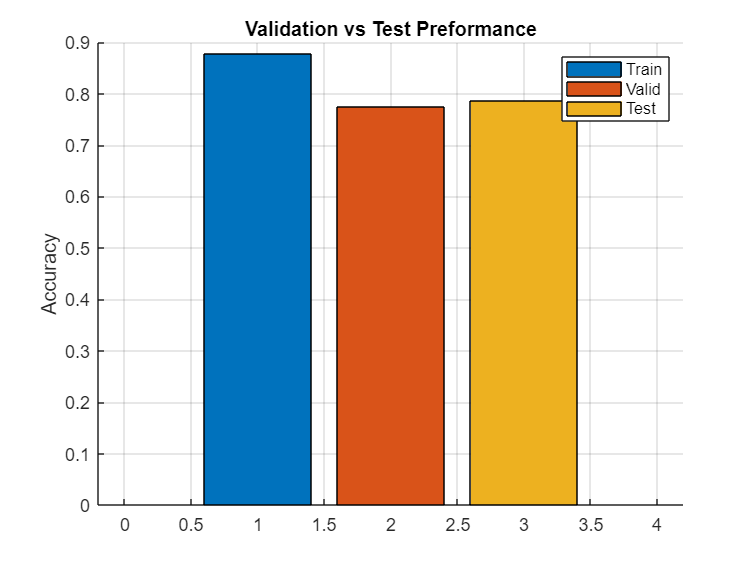

% Plot the validation on a graph
% NOTE, the 2 folds is not preferable, but it took nearly 2 hours to run as
% is with 2 folds, so I will need to work on that.
KfoldTest = figure;
hold on
b1 = bar(1, trainAccuracyFinal,'DisplayName','Train');
b2 = bar(2, valAccuracyFinal,'DisplayName','Valid');
b3 = bar(3, testAccuracyFinal,'DisplayName','Test');
xlabel(' ');
ylabel('Accuracy');
title('Validation vs Test Preformance');
grid on;
legend;
filename = sprintf('cnnAccuracy.png');
outputFile = fullfile("figures/",filename);
exportgraphics(KfoldTest,outputFile,'Resolution',600);

### Table of Data